% Data: 2026-09-24
% Variantas: 1
% Ieva Masiliauskaitė

clear; clc;


## 1 uzd a)

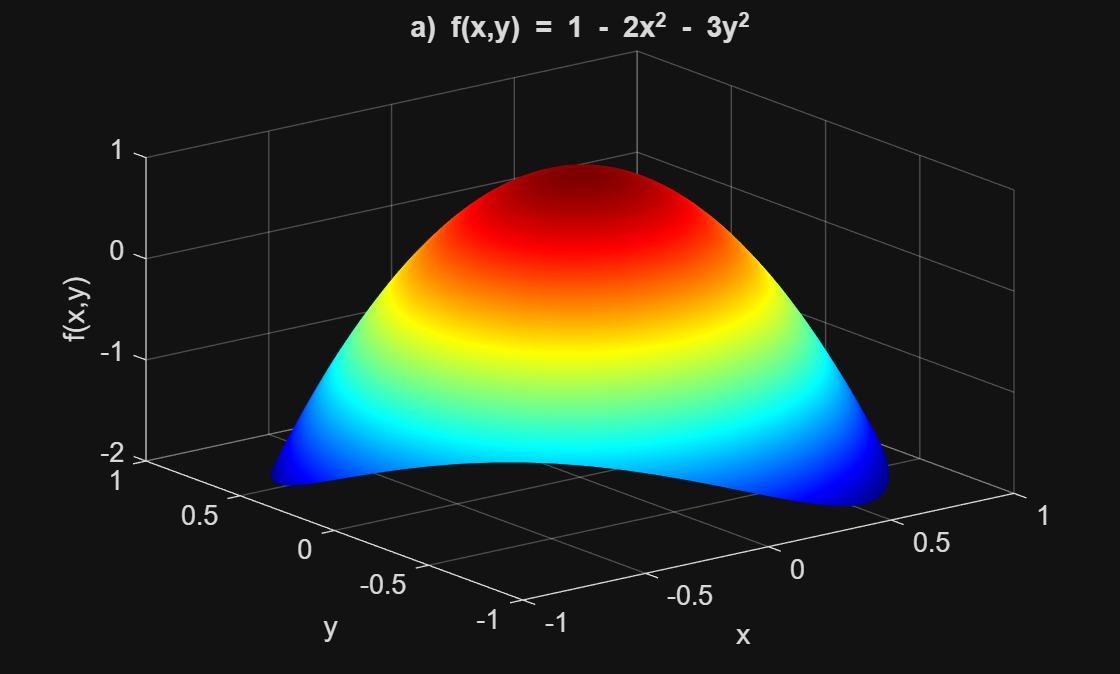

% f(x,y) = 1 - 2x^2 - 3y^2, x = r*cos(theta), y = r*sin(theta)
theta = linspace(0, 2*pi, 60);
r = linspace(0, 1, 30);
[R, T] = meshgrid(r, theta);
X = R .* cos(T);
Y = R .* sin(T);
Z = 1 - 2*X.^2 - 3*Y.^2;

figure;
h1 = surf(X, Y, Z);
colormap(jet);
shading interp;
rotate(h1, [0 0 1], 45);
title('a) f(x,y) = 1 - 2x^2 - 3y^2');
xlabel('x'); ylabel('y'); zlabel('f(x,y)');
grid on;

## b)

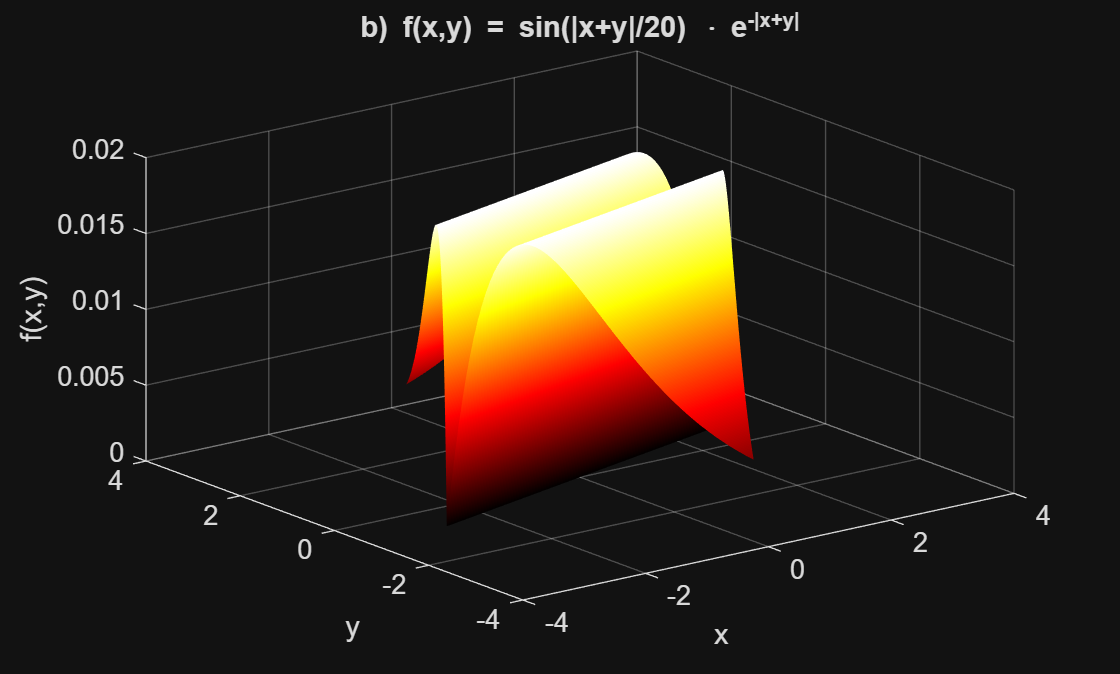

% f(x,y) = sin(|x+y|/20) * exp(-|x+y|), x,y is [-2; 2]
[X, Y] = meshgrid(linspace(-2, 2, 80));
Z = sin(abs(X + Y) / 20) .* exp(-abs(X + Y));

figure;
h2 = surf(X, Y, Z);
colormap(hot);
shading interp;
rotate(h2, [0 0 1], 60);
title('b) f(x,y) = sin(|x+y|/20) \cdot e^{-|x+y|}');
xlabel('x'); ylabel('y'); zlabel('f(x,y)');
grid on;

## PAPILDOMA

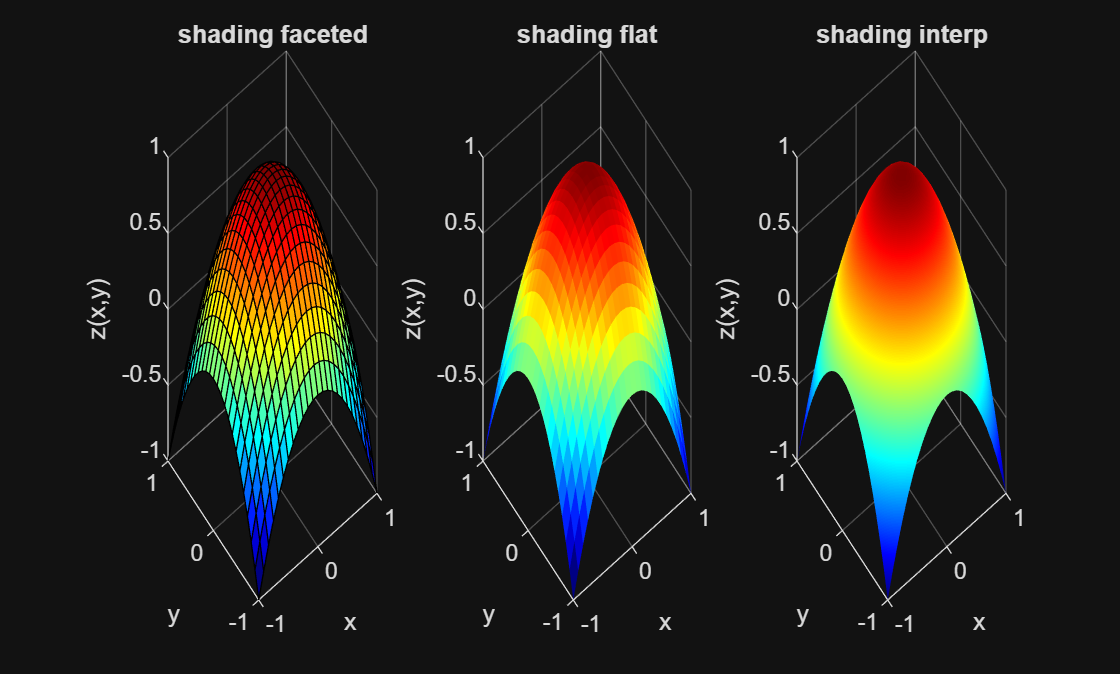

[X, Y] = meshgrid(linspace(-1, 1, 25));
Z = 1 - (X.^2 + Y.^2);

figure;
tipai = {'faceted', 'flat', 'interp'};
for k = 1:3 
    subplot(1, 3, k);
    surf(X, Y, Z);
    shading(tipai{k});
    colormap(jet);
    title(['shading ' tipai{k}]);
    xlabel('x'); ylabel('y'); zlabel('z(x,y)');
    grid on 
end